start = tic;
addpath functions\
addpath rawData\
latex_interpreter

systemName = 'ieee123'

systemName = 'ieee123'

numAreas = 4

numAreas = 4


actualBusNums = [1:36, 119, 126, 127, 117, 54:68, 122, 118, 37:53, 120, 125, 128, 69:116, 121, 123, 124]';
N = max(actualBusNums);

loss_min = true;   % CVR  = 0, Loss minimization = 1;
itrMax = 150; %Max no. of permissible iterations for optimizing an area
% Stopping Criterion:
eps = 0.001 ; % Tolerance
displayTables = false;
displayNetworkGraphs = true;
displayActualBusNumbersInGraphs = false;
savePlots = false;
CVR = [0; 0]; %as opposed to [0.6; 3.0]

load_mult = 1;
gen_mult = 1;

kVA_B = 1000;                                        % base kVA
kV_B = 4.16/sqrt(3);  

systemDataFolder = strcat("rawData/", systemName, "/numAreas_", num2str(numAreas), "/");
connectionBusesFilename = strcat(systemDataFolder, "connectionBuses.txt");
CBTable = readtable(connectionBusesFilename);
CBMatrix = table2array(CBTable);

connectionBuses_FullFilename = strcat(systemDataFolder, "connectionBuses_Full.txt");
CB_FullTable = readtable(connectionBuses_FullFilename);
CB_FullTable.S_childArea = zeros(size(CB_FullTable, 1), 1);
CB_FullTable.v2_parentArea = 1.03^2*ones(size(CB_FullTable, 1), 1)

CB_FullTable = 3×8 table
    parentArea    childArea    connectingBus_parentArea_parentIdx    connectingBus_childArea_parentIdx    connectingBus_parentArea_childIdx    connectingBus_childArea_childIdx    S_childArea    v2_parentArea
    __________    _________    __________________________________    _________________________________    _________________________________    ________________________________    ___________    _____________

        1             2                        15                                   40                                    1                                   2                         0            1.0609    
        1             3                        20                             

S_childAreas =      0
     0


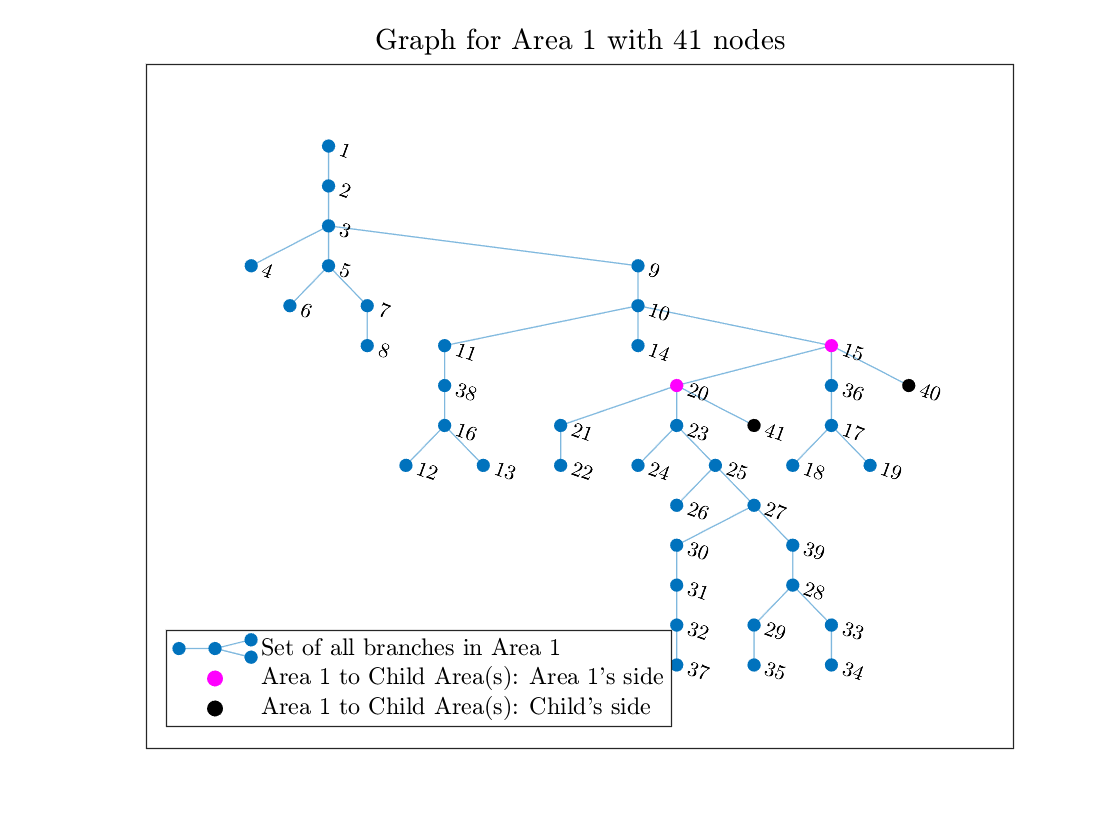

T_Area =      1     2
     2     3
     3     4
     3     5
     5     6
     5     7
     7     8
     3     9
     9    10
    10    11


ChildB = 2

ParentB = 1

PoC = 1

ChildB =      3
     4
     8


ParentB = 2

PoC = 2


ChildB =

  0×1 empty double column vector



ParentB = 3

PoC =      3
     4
     8


ChildB =      5
     6


ParentB = 4

PoC =      3
     4
     8



ChildB =

  0×1 empty double column vector



ParentB = 5

PoC =      5
     6


ChildB = 7

ParentB = 6

PoC =      5
     6



ChildB =

  0×1 empty double column vector



ParentB = 7

PoC = 7

ChildB = 9

ParentB = 8

PoC =      3
     4
     8


ChildB =     10
    15
    16


ParentB = 9

PoC = 9

ChildB = 11

ParentB = 10

PoC =     10
    15
    16



ChildB =

  0×1 empty double column vector



ParentB = 13

PoC =     13
    14



ChildB =

  0×1 empty double column vector



ParentB = 14

PoC =     13
    14



ChildB =

  0×1 empty double column vector



ParentB = 15

PoC =     10
    15
    16


ChildB =     17
    36
    40


ParentB = 16

PoC =     10
    15
    16


ChildB =     13
    14


ParentB = 12

PoC = 12

ChildB =     38
    39


ParentB = 37

PoC = 37


ChildB =

  0×1 empty double column vector



ParentB = 38

PoC =     38
    39



ChildB =

  0×1 empty double column vector



ParentB = 39

PoC =     38
    39


ChildB =     18
    20
    35


ParentB = 17

PoC =     17
    36
    40


ChildB = 19

ParentB = 18

PoC =     18
    20
    35



ChildB =

  0×1 empty double column vector



ParentB = 19

PoC = 19

ChildB =     21
    22


ParentB = 20

PoC =     18
    20
    35



ChildB =

  0×1 empty double column vector



ParentB = 21

PoC =     21
    22


ChildB =     23
    24


ParentB = 22

PoC =     21
    22



ChildB =

  0×1 empty double column vector



ParentB = 23

PoC =     23
    24


ChildB =     25
    29


ParentB = 24

PoC =     23
    24


ChildB =     31
    33


ParentB = 30

PoC = 30

ChildB = 32

ParentB = 31

PoC =     31
    33


ChildB = 26

ParentB = 25

PoC =     25
    29


ChildB = 27

ParentB = 26

PoC = 26

ChildB = 28

ParentB = 27

PoC = 27

ChildB = 34

ParentB = 33

PoC =     31
    33



ChildB =

  0×1 empty double column vector



ParentB = 34

PoC = 34


ChildB =

  0×1 empty double column vector



ParentB = 32

PoC = 32

ChildB = 37

ParentB = 36

PoC =     17
    36
    40



ChildB =

  0×1 empty double column vector



ParentB = 28

PoC = 28

ChildB = 12

ParentB = 11

PoC = 11

ChildB = 30

ParentB = 29

PoC =     25
    29



ChildB =

  0×1 empty double column vector



ParentB = 40

PoC =     17
    36
    40



ChildB =

  0×1 empty double column vector



ParentB = 35

PoC =     18
    20
    35


S_childAreas = 0

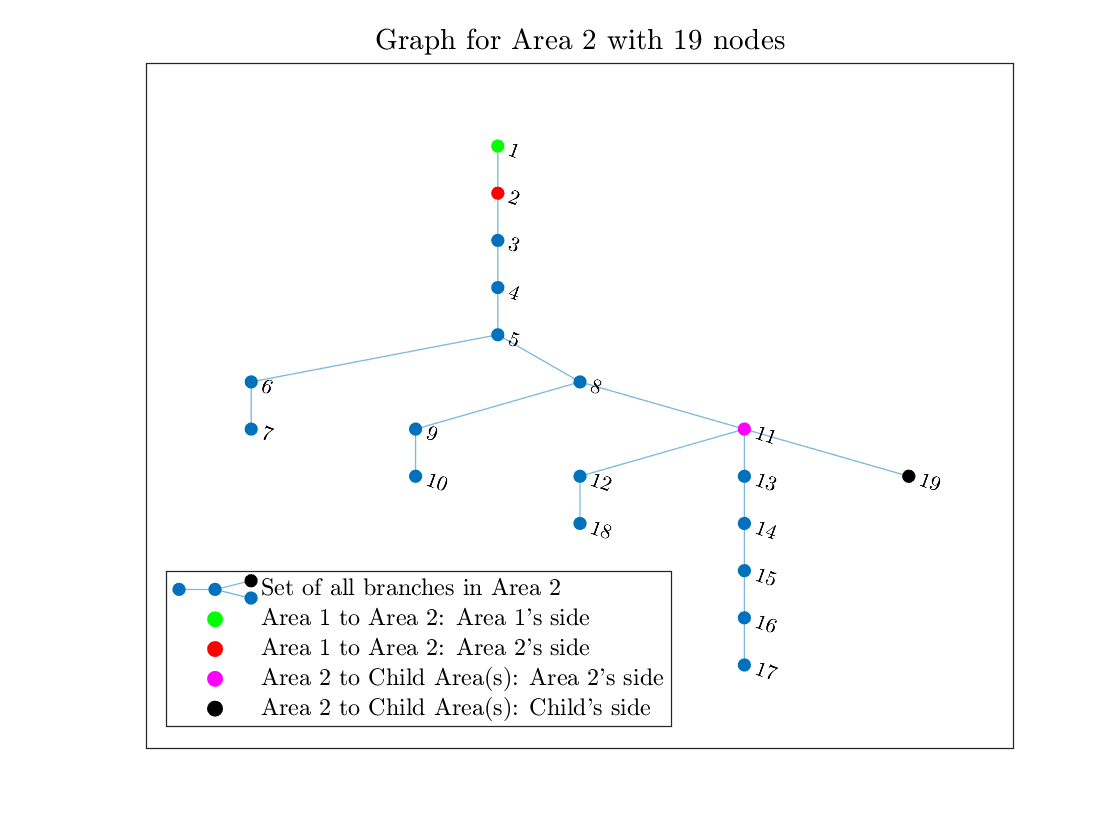

T_Area =      1     2
     2     3
     3     4
     4     5
     5     6
     6     7
     5     8
     8     9
     9    10
     8    11


ChildB = 2

ParentB = 1

PoC = 1

ChildB = 3

ParentB = 2

PoC = 2

ChildB = 4

ParentB = 3

PoC = 3

ChildB =      5
     7


ParentB = 4

PoC = 4

ChildB = 6

ParentB = 5

PoC =      5
     7



ChildB =

  0×1 empty double column vector



ParentB = 6

PoC = 6

ChildB =      8
    10


ParentB = 7

PoC =      5
     7


ChildB = 9

ParentB = 8

PoC =      8
    10



ChildB =

  0×1 empty double column vector



ParentB = 9

PoC = 9

ChildB =     11
    13
    18


ParentB = 10

PoC =      8
    10


ChildB = 12

ParentB = 11

PoC =     11
    13
    18


ChildB = 14

ParentB = 13

PoC =     11
    13
    18


ChildB = 15

ParentB = 14

PoC = 14

ChildB = 16

ParentB = 15

PoC = 15

ChildB = 17

ParentB = 16

PoC = 16


ChildB =

  0×1 empty double column vector



ParentB = 17

PoC = 17


ChildB =

  0×1 empty double column vector



ParentB = 12

PoC = 12


ChildB =

  0×1 empty double column vector



ParentB = 18

PoC = 3×1
    11
    13
    18



S_childAreas =

  0×1 empty double column vector



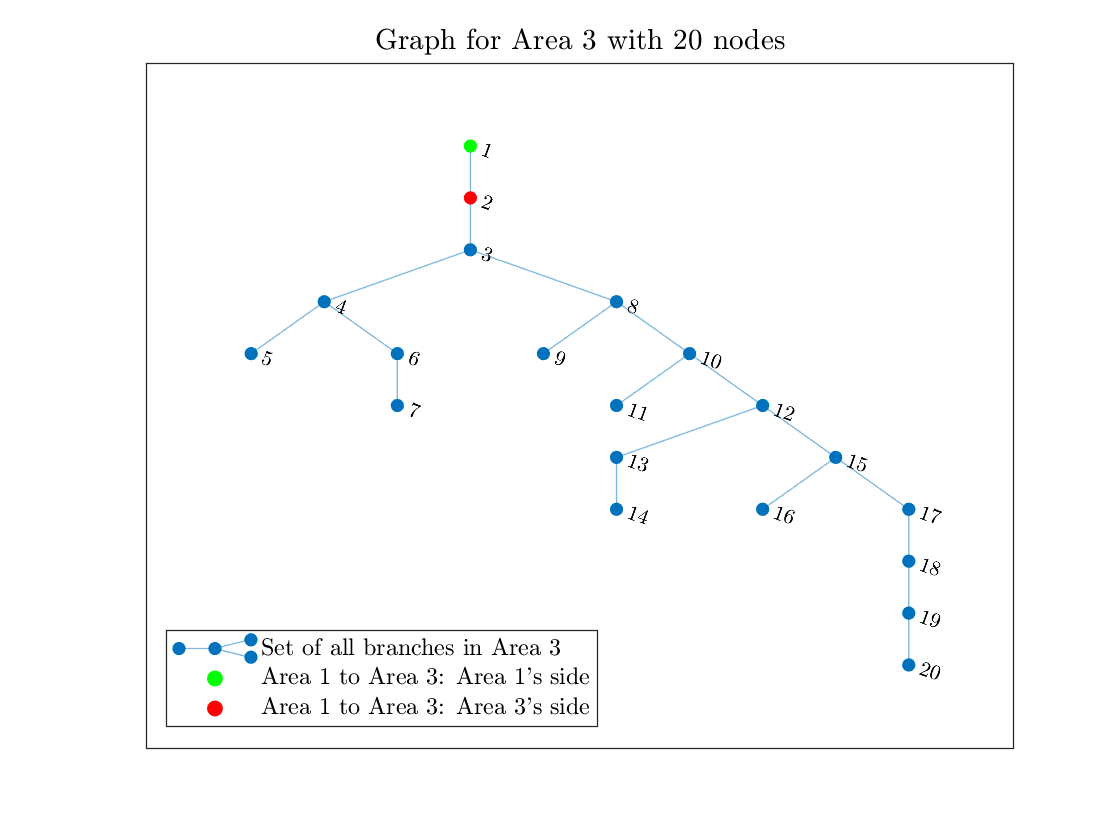

T_Area = 19×2
     1     2
     2     3
     3     4
     4     5
     4     6
     6     7
     3     8
     8     9
     8    10
    10    11


ChildB = 2

ParentB = 1

PoC = 1

ChildB = 2×1
     3
     7


ParentB = 2

PoC = 2

ChildB = 2×1
     4
     5


ParentB = 3

PoC = 2×1
     3
     7



ChildB =

  0×1 empty double column vector



ParentB = 4

PoC = 2×1
     4
     5


ChildB = 6

ParentB = 5

PoC = 2×1
     4
     5



ChildB =

  0×1 empty double column vector



ParentB = 6

PoC = 6

ChildB = 2×1
     8
     9


ParentB = 7

PoC = 2×1
     3
     7



ChildB =

  0×1 empty double column vector



ParentB = 8

PoC = 2×1
     8
     9


ChildB = 2×1
    10
    11


ParentB = 9

PoC = 2×1
     8
     9



ChildB =

  0×1 empty double column vector



ParentB = 10

PoC = 2×1
    10
    11


ChildB = 2×1
    12
    14


ParentB = 11

PoC = 2×1
    10
    11


ChildB = 13

ParentB = 12

PoC = 2×1
    12
    14



ChildB =

  0×1 empty double column vector



ParentB = 13

PoC = 13

ChildB = 2×1
    15
    16


ParentB = 14

PoC = 2×1
    12
    14



ChildB =

  0×1 empty double column vector



ParentB = 15

PoC = 2×1
    15
    16


ChildB = 17

ParentB = 16

PoC = 2×1
    15
    16


ChildB = 18

ParentB = 17

PoC = 17

ChildB = 19

ParentB = 18

PoC = 18


ChildB =

  0×1 empty double column vector



ParentB = 19

PoC = 19


S_childAreas =

  0×1 empty double column vector



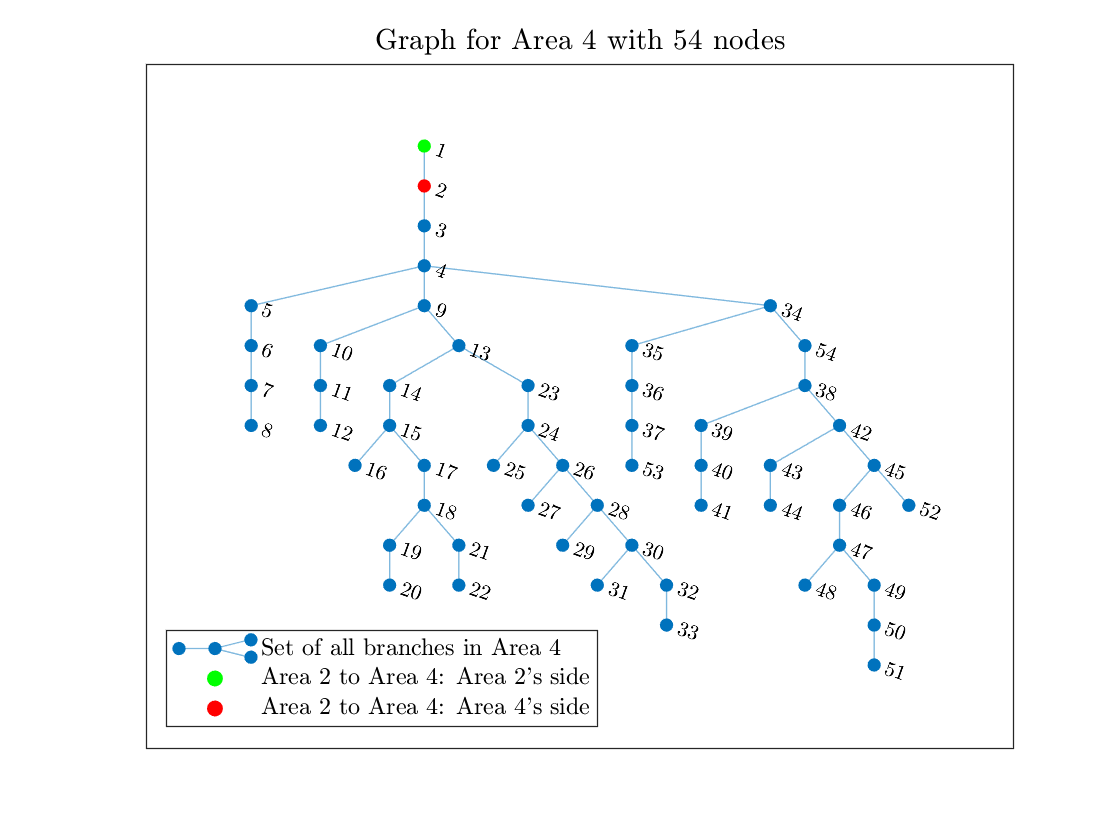

T_Area = 53×2
     1     2
     2     3
     3     4
     4     5
     5     6
     6     7
     7     8
     4     9
     9    10
    10    11


ChildB = 2

ParentB = 1

PoC = 1

ChildB = 3

ParentB = 2

PoC = 2

ChildB = 3×1
     4
     8
    33


ParentB = 3

PoC = 3

ChildB = 5

ParentB = 4

PoC = 3×1
     4
     8
    33


ChildB = 6

ParentB = 5

PoC = 5

ChildB = 7

ParentB = 6

PoC = 6


ChildB =

  0×1 empty double column vector



ParentB = 7

PoC = 7

ChildB = 2×1
     9
    12


ParentB = 8

PoC = 3×1
     4
     8
    33


ChildB = 10

ParentB = 9

PoC = 2×1
     9
    12


ChildB = 11

ParentB = 10

PoC = 10


ChildB =

  0×1 empty double column vector



ParentB = 11

PoC = 11

ChildB = 2×1
    13
    22


ParentB = 12

PoC = 2×1
     9
    12


ChildB = 14

ParentB = 13

PoC = 2×1
    13
    22


ChildB = 2×1
    15
    16


ParentB = 14

PoC = 14


ChildB =

  0×1 empty double column vector



ParentB = 15

PoC = 2×1
    15
    16


ChildB = 17

ParentB = 16

PoC = 2×1
    15
    16


ChildB = 2×1
    18
    20


ParentB = 17

PoC = 17

ChildB = 19

ParentB = 18

PoC = 2×1
    18
    20



ChildB =

  0×1 empty double column vector



ParentB = 19

PoC = 19

ChildB = 21

ParentB = 20

PoC = 2×1
    18
    20



ChildB =

  0×1 empty double column vector



ParentB = 21

PoC = 21

ChildB = 23

ParentB = 22

PoC = 2×1
    13
    22


ChildB = 2×1
    24
    25


ParentB = 23

PoC = 23


ChildB =

  0×1 empty double column vector



ParentB = 24

PoC = 2×1
    24
    25


ChildB = 2×1
    26
    27


ParentB = 25

PoC = 2×1
    24
    25



ChildB =

  0×1 empty double column vector



ParentB = 26

PoC = 2×1
    26
    27


ChildB = 2×1
    28
    29


ParentB = 27

PoC = 2×1
    26
    27



ChildB =

  0×1 empty double column vector



ParentB = 28

PoC = 2×1
    28
    29


ChildB = 2×1
    30
    31


ParentB = 29

PoC = 2×1
    28
    29



ChildB =

  0×1 empty double column vector



ParentB = 30

PoC = 2×1
    30
    31


ChildB = 32

ParentB = 31

PoC = 2×1
    30
    31



ChildB =

  0×1 empty double column vector



ParentB = 32

PoC = 32

ChildB = 2×1
    34
    38


ParentB = 33

PoC = 3×1
     4
     8
    33


ChildB = 35

ParentB = 34

PoC = 2×1
    34
    38


ChildB = 36

ParentB = 35

PoC = 35

ChildB = 37

ParentB = 36

PoC = 36

ChildB = 2×1
    40
    43


ParentB = 39

PoC = 39

ChildB = 41

ParentB = 40

PoC = 2×1
    40
    43


ChildB = 42

ParentB = 41

PoC = 41


ChildB =

  0×1 empty double column vector



ParentB = 42

PoC = 42

ChildB = 2×1
    44
    46


ParentB = 43

PoC = 2×1
    40
    43


ChildB = 45

ParentB = 44

PoC = 2×1
    44
    46



ChildB =

  0×1 empty double column vector



ParentB = 45

PoC = 45

ChildB = 2×1
    47
    53


ParentB = 46

PoC = 2×1
    44
    46


ChildB = 48

ParentB = 47

PoC = 2×1
    47
    53


ChildB = 2×1
    49
    50


ParentB = 48

PoC = 48


ChildB =

  0×1 empty double column vector



ParentB = 49

PoC = 2×1
    49
    50


ChildB = 51

ParentB = 50

PoC = 2×1
    49
    50


ChildB = 52

ParentB = 51

PoC = 51


ChildB =

  0×1 empty double column vector



ParentB = 52

PoC = 52


ChildB =

  0×1 empty double column vector



ParentB = 53

PoC = 2×1
    47
    53



ChildB =

  0×1 empty double column vector



ParentB = 37

PoC = 37

ChildB = 39

ParentB = 38

PoC = 2×1
    34
    38


S_childAreas = 2×1
   0.1196 + 0.0580i
   0.1639 + 0.0990i


T_Area = 40×2
     1     2
     2     3
     3     4
     3     5
     5     6
     5     7
     7     8
     3     9
     9    10
    10    11


ChildB = 2

ParentB = 1

PoC = 1

ChildB = 3×1
     3
     4
     8


ParentB = 2

PoC = 2


ChildB =

  0×1 empty double column vector



ParentB = 3

PoC = 3×1
     3
     4
     8


ChildB = 2×1
     5
     6


ParentB = 4

PoC = 3×1
     3
     4
     8



ChildB =

  0×1 empty double column vector



ParentB = 5

PoC = 2×1
     5
     6


ChildB = 7

ParentB = 6

PoC = 2×1
     5
     6



ChildB =

  0×1 empty double column vector



ParentB = 7

PoC = 7

ChildB = 9

ParentB = 8

PoC = 3×1
     3
     4
     8


ChildB = 3×1
    10
    15
    16


ParentB = 9

PoC = 9

ChildB = 11

ParentB = 10

PoC = 3×1
    10
    15
    16



ChildB =

  0×1 empty double column vector



ParentB = 13

PoC = 2×1
    13
    14



ChildB =

  0×1 empty double column vector



ParentB = 14

PoC = 2×1
    13
    14



ChildB =

  0×1 empty double column vector



ParentB = 15

PoC = 3×1
    10
    15
    16


ChildB = 3×1
    17
    36
    40


ParentB = 16

PoC = 3×1
    10
    15
    16


ChildB = 2×1
    13
    14


ParentB = 12

PoC = 12

ChildB = 2×1
    38
    39


ParentB = 37

PoC = 37


ChildB =

  0×1 empty double column vector



ParentB = 38

PoC = 2×1
    38
    39



ChildB =

  0×1 empty double column vector



ParentB = 39

PoC = 2×1
    38
    39


ChildB = 3×1
    18
    20
    35


ParentB = 17

PoC = 3×1
    17
    36
    40


ChildB = 19

ParentB = 18

PoC = 3×1
    18
    20
    35



ChildB =

  0×1 empty double column vector



ParentB = 19

PoC = 19

ChildB = 2×1
    21
    22


ParentB = 20

PoC = 3×1
    18
    20
    35



ChildB =

  0×1 empty double column vector



ParentB = 21

PoC = 2×1
    21
    22


ChildB = 2×1
    23
    24


ParentB = 22

PoC = 2×1
    21
    22



ChildB =

  0×1 empty double column vector



ParentB = 23

PoC = 2×1
    23
    24


ChildB = 2×1
    25
    29


ParentB = 24

PoC = 2×1
    23
    24


ChildB = 2×1
    31
    33


ParentB = 30

PoC = 30

ChildB = 32

ParentB = 31

PoC = 2×1
    31
    33


ChildB = 26

ParentB = 25

PoC = 2×1
    25
    29


ChildB = 27

ParentB = 26

PoC = 26

ChildB = 28

ParentB = 27

PoC = 27

ChildB = 34

ParentB = 33

PoC = 2×1
    31
    33



ChildB =

  0×1 empty double column vector



ParentB = 34

PoC = 34


ChildB =

  0×1 empty double column vector



ParentB = 32

PoC = 32

ChildB = 37

ParentB = 36

PoC = 3×1
    17
    36
    40



ChildB =

  0×1 empty double column vector



ParentB = 28

PoC = 28

ChildB = 12

ParentB = 11

PoC = 11

ChildB = 30

ParentB = 29

PoC = 2×1
    25
    29



ChildB =

  0×1 empty double column vector



ParentB = 40

PoC = 3×1
    17
    36
    40



ChildB =

  0×1 empty double column vector



ParentB = 35

PoC = 3×1
    18
    20
    35


S_childAreas = 0.3101 - 0.0628i

T_Area = 18×2
     1     2
     2     3
     3     4
     4     5
     5     6
     6     7
     5     8
     8     9
     9    10
     8    11


ChildB = 2

ParentB = 1

PoC = 1

ChildB = 3

ParentB = 2

PoC = 2

ChildB = 4

ParentB = 3

PoC = 3

ChildB = 2×1
     5
     7


ParentB = 4

PoC = 4

ChildB = 6

ParentB = 5

PoC = 2×1
     5
     7



ChildB =

  0×1 empty double column vector



ParentB = 6

PoC = 6

ChildB = 2×1
     8
    10


ParentB = 7

PoC = 2×1
     5
     7


ChildB = 9

ParentB = 8

PoC = 2×1
     8
    10



ChildB =

  0×1 empty double column vector



ParentB = 9

PoC = 9

ChildB = 3×1
    11
    13
    18


ParentB = 10

PoC = 2×1
     8
    10


ChildB = 12

ParentB = 11

PoC = 3×1
    11
    13
    18


ChildB = 14

ParentB = 13

PoC = 3×1
    11
    13
    18


ChildB = 15

ParentB = 14

PoC = 14

ChildB = 16

ParentB = 15

PoC = 15

ChildB = 17

ParentB = 16

PoC = 16


ChildB =

  0×1 empty double column vector



ParentB = 17

PoC = 17


ChildB =

  0×1 empty double column vector



ParentB = 12

PoC = 12


ChildB =

  0×1 empty double column vector



ParentB = 18

PoC = 3×1
    11
    13
    18



S_childAreas =

  0×1 empty double column vector



T_Area = 19×2
     1     2
     2     3
     3     4
     4     5
     4     6
     6     7
     3     8
     8     9
     8    10
    10    11


ChildB = 2

ParentB = 1

PoC = 1

ChildB = 2×1
     3
     7


ParentB = 2

PoC = 2

ChildB = 2×1
     4
     5


ParentB = 3

PoC = 2×1
     3
     7



ChildB =

  0×1 empty double column vector



ParentB = 4

PoC = 2×1
     4
     5


ChildB = 6

ParentB = 5

PoC = 2×1
     4
     5



ChildB =

  0×1 empty double column vector



ParentB = 6

PoC = 6

ChildB = 2×1
     8
     9


ParentB = 7

PoC = 2×1
     3
     7



ChildB =

  0×1 empty double column vector



ParentB = 8

PoC = 2×1
     8
     9


ChildB = 2×1
    10
    11


ParentB = 9

PoC = 2×1
     8
     9



ChildB =

  0×1 empty double column vector



ParentB = 10

PoC = 2×1
    10
    11


ChildB = 2×1
    12
    14


ParentB = 11

PoC = 2×1
    10
    11


ChildB = 13

ParentB = 12

PoC = 2×1
    12
    14



ChildB =

  0×1 empty double column vector



ParentB = 13

PoC = 13

ChildB = 2×1
    15
    16


ParentB = 14

PoC = 2×1
    12
    14



ChildB =

  0×1 empty double column vector



ParentB = 15

PoC = 2×1
    15
    16


ChildB = 17

ParentB = 16

PoC = 2×1
    15
    16


ChildB = 18

ParentB = 17

PoC = 17

ChildB = 19

ParentB = 18

PoC = 18


ChildB =

  0×1 empty double column vector



ParentB = 19

PoC = 19


S_childAreas =

  0×1 empty double column vector



T_Area = 53×2
     1     2
     2     3
     3     4
     4     5
     5     6
     6     7
     7     8
     4     9
     9    10
    10    11


ChildB = 2

ParentB = 1

PoC = 1

ChildB = 3

ParentB = 2

PoC = 2

ChildB = 3×1
     4
     8
    33


ParentB = 3

PoC = 3

ChildB = 5

ParentB = 4

PoC = 3×1
     4
     8
    33


ChildB = 6

ParentB = 5

PoC = 5

ChildB = 7

ParentB = 6

PoC = 6


ChildB =

  0×1 empty double column vector



ParentB = 7

PoC = 7

ChildB = 2×1
     9
    12


ParentB = 8

PoC = 3×1
     4
     8
    33


ChildB = 10

ParentB = 9

PoC = 2×1
     9
    12


ChildB = 11

ParentB = 10

PoC = 10


ChildB =

  0×1 empty double column vector



ParentB = 11

PoC = 11

ChildB = 2×1
    13
    22


ParentB = 12

PoC = 2×1
     9
    12


ChildB = 14

ParentB = 13

PoC = 2×1
    13
    22


ChildB = 2×1
    15
    16


ParentB = 14

PoC = 14


ChildB =

  0×1 empty double column vector



ParentB = 15

PoC = 2×1
    15
    16


ChildB = 17

ParentB = 16

PoC = 2×1
    15
    16


ChildB = 2×1
    18
    20


ParentB = 17

PoC = 17

ChildB = 19

ParentB = 18

PoC = 2×1
    18
    20



ChildB =

  0×1 empty double column vector



ParentB = 19

PoC = 19

ChildB = 21

ParentB = 20

PoC = 2×1
    18
    20



ChildB =

  0×1 empty double column vector



ParentB = 21

PoC = 21

ChildB = 23

ParentB = 22

PoC = 2×1
    13
    22


ChildB = 2×1
    24
    25


ParentB = 23

PoC = 23


ChildB =

  0×1 empty double column vector



ParentB = 24

PoC = 2×1
    24
    25


ChildB = 2×1
    26
    27


ParentB = 25

PoC = 2×1
    24
    25



ChildB =

  0×1 empty double column vector



ParentB = 26

PoC = 2×1
    26
    27


ChildB = 2×1
    28
    29


ParentB = 27

PoC = 2×1
    26
    27



ChildB =

  0×1 empty double column vector



ParentB = 28

PoC = 2×1
    28
    29


ChildB = 2×1
    30
    31


ParentB = 29

PoC = 2×1
    28
    29



ChildB =

  0×1 empty double column vector



ParentB = 30

PoC = 2×1
    30
    31


ChildB = 32

ParentB = 31

PoC = 2×1
    30
    31



ChildB =

  0×1 empty double column vector



ParentB = 32

PoC = 32

ChildB = 2×1
    34
    38


ParentB = 33

PoC = 3×1
     4
     8
    33


ChildB = 35

ParentB = 34

PoC = 2×1
    34
    38


ChildB = 36

ParentB = 35

PoC = 35

ChildB = 37

ParentB = 36

PoC = 36

ChildB = 2×1
    40
    43


ParentB = 39

PoC = 39

ChildB = 41

ParentB = 40

PoC = 2×1
    40
    43


ChildB = 42

ParentB = 41

PoC = 41


ChildB =

  0×1 empty double column vector



ParentB = 42

PoC = 42

ChildB = 2×1
    44
    46


ParentB = 43

PoC = 2×1
    40
    43


ChildB = 45

ParentB = 44

PoC = 2×1
    44
    46



ChildB =

  0×1 empty double column vector



ParentB = 45

PoC = 45

ChildB = 2×1
    47
    53


ParentB = 46

PoC = 2×1
    44
    46


ChildB = 48

ParentB = 47

PoC = 2×1
    47
    53


ChildB = 2×1
    49
    50


ParentB = 48

PoC = 48


ChildB =

  0×1 empty double column vector



ParentB = 49

PoC = 2×1
    49
    50


ChildB = 51

ParentB = 50

PoC = 2×1
    49
    50


ChildB = 52

ParentB = 51

PoC = 51


ChildB =

  0×1 empty double column vector



ParentB = 52

PoC = 52


ChildB =

  0×1 empty double column vector



ParentB = 53

PoC = 2×1
    47
    53



ChildB =

  0×1 empty double column vector



ParentB = 37

PoC = 37

ChildB = 39

ParentB = 38

PoC = 2×1
    34
    38


S_childAreas = 2×1
   0.4324 + 0.0039i
   0.1639 + 0.0990i


T_Area = 40×2
     1     2
     2     3
     3     4
     3     5
     5     6
     5     7
     7     8
     3     9
     9    10
    10    11


ChildB = 2

ParentB = 1

PoC = 1

ChildB = 3×1
     3
     4
     8


ParentB = 2

PoC = 2


ChildB =

  0×1 empty double column vector



ParentB = 3

PoC = 3×1
     3
     4
     8


ChildB = 2×1
     5
     6


ParentB = 4

PoC = 3×1
     3
     4
     8



ChildB =

  0×1 empty double column vector



ParentB = 5

PoC = 2×1
     5
     6


ChildB = 7

ParentB = 6

PoC = 2×1
     5
     6



ChildB =

  0×1 empty double column vector



ParentB = 7

PoC = 7

ChildB = 9

ParentB = 8

PoC = 3×1
     3
     4
     8


ChildB = 3×1
    10
    15
    16


ParentB = 9

PoC = 9

ChildB = 11

ParentB = 10

PoC = 3×1
    10
    15
    16



ChildB =

  0×1 empty double column vector



ParentB = 13

PoC = 2×1
    13
    14



ChildB =

  0×1 empty double column vector



ParentB = 14

PoC = 2×1
    13
    14



ChildB =

  0×1 empty double column vector



ParentB = 15

PoC = 3×1
    10
    15
    16


ChildB = 3×1
    17
    36
    40


ParentB = 16

PoC = 3×1
    10
    15
    16


ChildB = 2×1
    13
    14


ParentB = 12

PoC = 12

ChildB = 2×1
    38
    39


ParentB = 37

PoC = 37


ChildB =

  0×1 empty double column vector



ParentB = 38

PoC = 2×1
    38
    39



ChildB =

  0×1 empty double column vector



ParentB = 39

PoC = 2×1
    38
    39


ChildB = 3×1
    18
    20
    35


ParentB = 17

PoC = 3×1
    17
    36
    40


ChildB = 19

ParentB = 18

PoC = 3×1
    18
    20
    35



ChildB =

  0×1 empty double column vector



ParentB = 19

PoC = 19

ChildB = 2×1
    21
    22


ParentB = 20

PoC = 3×1
    18
    20
    35



ChildB =

  0×1 empty double column vector



ParentB = 21

PoC = 2×1
    21
    22


ChildB = 2×1
    23
    24


ParentB = 22

PoC = 2×1
    21
    22



ChildB =

  0×1 empty double column vector



ParentB = 23

PoC = 2×1
    23
    24


ChildB = 2×1
    25
    29


ParentB = 24

PoC = 2×1
    23
    24


ChildB = 2×1
    31
    33


ParentB = 30

PoC = 30

ChildB = 32

ParentB = 31

PoC = 2×1
    31
    33


ChildB = 26

ParentB = 25

PoC = 2×1
    25
    29


ChildB = 27

ParentB = 26

PoC = 26

ChildB = 28

ParentB = 27

PoC = 27

ChildB = 34

ParentB = 33

PoC = 2×1
    31
    33



ChildB =

  0×1 empty double column vector



ParentB = 34

PoC = 34


ChildB =

  0×1 empty double column vector



ParentB = 32

PoC = 32

ChildB = 37

ParentB = 36

PoC = 3×1
    17
    36
    40



ChildB =

  0×1 empty double column vector



ParentB = 28

PoC = 28

ChildB = 12

ParentB = 11

PoC = 11

ChildB = 30

ParentB = 29

PoC = 2×1
    25
    29



ChildB =

  0×1 empty double column vector



ParentB = 40

PoC = 3×1
    17
    36
    40



ChildB =

  0×1 empty double column vector



ParentB = 35

PoC = 3×1
    18
    20
    35


S_childAreas = 0.3101 - 0.0628i

T_Area = 18×2
     1     2
     2     3
     3     4
     4     5
     5     6
     6     7
     5     8
     8     9
     9    10
     8    11


ChildB = 2

ParentB = 1

PoC = 1

ChildB = 3

ParentB = 2

PoC = 2

ChildB = 4

ParentB = 3

PoC = 3

ChildB = 2×1
     5
     7


ParentB = 4

PoC = 4

ChildB = 6

ParentB = 5

PoC = 2×1
     5
     7



ChildB =

  0×1 empty double column vector



ParentB = 6

PoC = 6

ChildB = 2×1
     8
    10


ParentB = 7

PoC = 2×1
     5
     7


ChildB = 9

ParentB = 8

PoC = 2×1
     8
    10



ChildB =

  0×1 empty double column vector



ParentB = 9

PoC = 9

ChildB = 3×1
    11
    13
    18


ParentB = 10

PoC = 2×1
     8
    10


ChildB = 12

ParentB = 11

PoC = 3×1
    11
    13
    18


ChildB = 14

ParentB = 13

PoC = 3×1
    11
    13
    18


ChildB = 15

ParentB = 14

PoC = 14

ChildB = 16

ParentB = 15

PoC = 15

ChildB = 17

ParentB = 16

PoC = 16


ChildB =

  0×1 empty double column vector



ParentB = 17

PoC = 17


ChildB =

  0×1 empty double column vector



ParentB = 12

PoC = 12


ChildB =

  0×1 empty double column vector



ParentB = 18

PoC = 3×1
    11
    13
    18



S_childAreas =

  0×1 empty double column vector



T_Area = 19×2
     1     2
     2     3
     3     4
     4     5
     4     6
     6     7
     3     8
     8     9
     8    10
    10    11


ChildB = 2

ParentB = 1

PoC = 1

ChildB = 2×1
     3
     7


ParentB = 2

PoC = 2

ChildB = 2×1
     4
     5


ParentB = 3

PoC = 2×1
     3
     7



ChildB =

  0×1 empty double column vector



ParentB = 4

PoC = 2×1
     4
     5


ChildB = 6

ParentB = 5

PoC = 2×1
     4
     5



ChildB =

  0×1 empty double column vector



ParentB = 6

PoC = 6

ChildB = 2×1
     8
     9


ParentB = 7

PoC = 2×1
     3
     7



ChildB =

  0×1 empty double column vector



ParentB = 8

PoC = 2×1
     8
     9


ChildB = 2×1
    10
    11


ParentB = 9

PoC = 2×1
     8
     9



ChildB =

  0×1 empty double column vector



ParentB = 10

PoC = 2×1
    10
    11


ChildB = 2×1
    12
    14


ParentB = 11

PoC = 2×1
    10
    11


ChildB = 13

ParentB = 12

PoC = 2×1
    12
    14



ChildB =

  0×1 empty double column vector



ParentB = 13

PoC = 13

ChildB = 2×1
    15
    16


ParentB = 14

PoC = 2×1
    12
    14



ChildB =

  0×1 empty double column vector



ParentB = 15

PoC = 2×1
    15
    16


ChildB = 17

ParentB = 16

PoC = 2×1
    15
    16


ChildB = 18

ParentB = 17

PoC = 17

ChildB = 19

ParentB = 18

PoC = 18


ChildB =

  0×1 empty double column vector



ParentB = 19

PoC = 19


S_childAreas =

  0×1 empty double column vector



T_Area = 53×2
     1     2
     2     3
     3     4
     4     5
     5     6
     6     7
     7     8
     4     9
     9    10
    10    11


ChildB = 2

ParentB = 1

PoC = 1

ChildB = 3

ParentB = 2

PoC = 2

ChildB = 3×1
     4
     8
    33


ParentB = 3

PoC = 3

ChildB = 5

ParentB = 4

PoC = 3×1
     4
     8
    33


ChildB = 6

ParentB = 5

PoC = 5

ChildB = 7

ParentB = 6

PoC = 6


ChildB =

  0×1 empty double column vector



ParentB = 7

PoC = 7

ChildB = 2×1
     9
    12


ParentB = 8

PoC = 3×1
     4
     8
    33


ChildB = 10

ParentB = 9

PoC = 2×1
     9
    12


ChildB = 11

ParentB = 10

PoC = 10


ChildB =

  0×1 empty double column vector



ParentB = 11

PoC = 11

ChildB = 2×1
    13
    22


ParentB = 12

PoC = 2×1
     9
    12


ChildB = 14

ParentB = 13

PoC = 2×1
    13
    22


ChildB = 2×1
    15
    16


ParentB = 14

PoC = 14


ChildB =

  0×1 empty double column vector



ParentB = 15

PoC = 2×1
    15
    16


ChildB = 17

ParentB = 16

PoC = 2×1
    15
    16


ChildB = 2×1
    18
    20


ParentB = 17

PoC = 17

ChildB = 19

ParentB = 18

PoC = 2×1
    18
    20



ChildB =

  0×1 empty double column vector



ParentB = 19

PoC = 19

ChildB = 21

ParentB = 20

PoC = 2×1
    18
    20



ChildB =

  0×1 empty double column vector



ParentB = 21

PoC = 21

ChildB = 23

ParentB = 22

PoC = 2×1
    13
    22


ChildB = 2×1
    24
    25


ParentB = 23

PoC = 23


ChildB =

  0×1 empty double column vector



ParentB = 24

PoC = 2×1
    24
    25


ChildB = 2×1
    26
    27


ParentB = 25

PoC = 2×1
    24
    25



ChildB =

  0×1 empty double column vector



ParentB = 26

PoC = 2×1
    26
    27


ChildB = 2×1
    28
    29


ParentB = 27

PoC = 2×1
    26
    27



ChildB =

  0×1 empty double column vector



ParentB = 28

PoC = 2×1
    28
    29


ChildB = 2×1
    30
    31


ParentB = 29

PoC = 2×1
    28
    29



ChildB =

  0×1 empty double column vector



ParentB = 30

PoC = 2×1
    30
    31


ChildB = 32

ParentB = 31

PoC = 2×1
    30
    31



ChildB =

  0×1 empty double column vector



ParentB = 32

PoC = 32

ChildB = 2×1
    34
    38


ParentB = 33

PoC = 3×1
     4
     8
    33


ChildB = 35

ParentB = 34

PoC = 2×1
    34
    38


ChildB = 36

ParentB = 35

PoC = 35

ChildB = 37

ParentB = 36

PoC = 36

ChildB = 2×1
    40
    43


ParentB = 39

PoC = 39

ChildB = 41

ParentB = 40

PoC = 2×1
    40
    43


ChildB = 42

ParentB = 41

PoC = 41


ChildB =

  0×1 empty double column vector



ParentB = 42

PoC = 42

ChildB = 2×1
    44
    46


ParentB = 43

PoC = 2×1
    40
    43


ChildB = 45

ParentB = 44

PoC = 2×1
    44
    46



ChildB =

  0×1 empty double column vector



ParentB = 45

PoC = 45

ChildB = 2×1
    47
    53


ParentB = 46

PoC = 2×1
    44
    46


ChildB = 48

ParentB = 47

PoC = 2×1
    47
    53


ChildB = 2×1
    49
    50


ParentB = 48

PoC = 48


ChildB =

  0×1 empty double column vector



ParentB = 49

PoC = 2×1
    49
    50


ChildB = 51

ParentB = 50

PoC = 2×1
    49
    50


ChildB = 52

ParentB = 51

PoC = 51


ChildB =

  0×1 empty double column vector



ParentB = 52

PoC = 52


ChildB =

  0×1 empty double column vector



ParentB = 53

PoC = 2×1
    47
    53



ChildB =

  0×1 empty double column vector



ParentB = 37

PoC = 37

ChildB = 39

ParentB = 38

PoC = 2×1
    34
    38


S_childAreas = 2×1
   0.4324 + 0.0040i
   0.1639 + 0.0990i


T_Area = 40×2
     1     2
     2     3
     3     4
     3     5
     5     6
     5     7
     7     8
     3     9
     9    10
    10    11


ChildB = 2

ParentB = 1

PoC = 1

ChildB = 3×1
     3
     4
     8


ParentB = 2

PoC = 2


ChildB =

  0×1 empty double column vector



ParentB = 3

PoC = 3×1
     3
     4
     8


ChildB = 2×1
     5
     6


ParentB = 4

PoC = 3×1
     3
     4
     8



ChildB =

  0×1 empty double column vector



ParentB = 5

PoC = 2×1
     5
     6


ChildB = 7

ParentB = 6

PoC = 2×1
     5
     6



ChildB =

  0×1 empty double column vector



ParentB = 7

PoC = 7

ChildB = 9

ParentB = 8

PoC = 3×1
     3
     4
     8


ChildB = 3×1
    10
    15
    16


ParentB = 9

PoC = 9

ChildB = 11

ParentB = 10

PoC = 3×1
    10
    15
    16



ChildB =

  0×1 empty double column vector



ParentB = 13

PoC = 2×1
    13
    14



ChildB =

  0×1 empty double column vector



ParentB = 14

PoC = 2×1
    13
    14



ChildB =

  0×1 empty double column vector



ParentB = 15

PoC = 3×1
    10
    15
    16


ChildB = 3×1
    17
    36
    40


ParentB = 16

PoC = 3×1
    10
    15
    16


ChildB = 2×1
    13
    14


ParentB = 12

PoC = 12

ChildB = 2×1
    38
    39


ParentB = 37

PoC = 37


ChildB =

  0×1 empty double column vector



ParentB = 38

PoC = 2×1
    38
    39



ChildB =

  0×1 empty double column vector



ParentB = 39

PoC = 2×1
    38
    39


ChildB = 3×1
    18
    20
    35


ParentB = 17

PoC = 3×1
    17
    36
    40


ChildB = 19

ParentB = 18

PoC = 3×1
    18
    20
    35



ChildB =

  0×1 empty double column vector



ParentB = 19

PoC = 19

ChildB = 2×1
    21
    22


ParentB = 20

PoC = 3×1
    18
    20
    35



ChildB =

  0×1 empty double column vector



ParentB = 21

PoC = 2×1
    21
    22


ChildB = 2×1
    23
    24


ParentB = 22

PoC = 2×1
    21
    22



ChildB =

  0×1 empty double column vector



ParentB = 23

PoC = 2×1
    23
    24


ChildB = 2×1
    25
    29


ParentB = 24

PoC = 2×1
    23
    24


ChildB = 2×1
    31
    33


ParentB = 30

PoC = 30

ChildB = 32

ParentB = 31

PoC = 2×1
    31
    33


ChildB = 26

ParentB = 25

PoC = 2×1
    25
    29


ChildB = 27

ParentB = 26

PoC = 26

ChildB = 28

ParentB = 27

PoC = 27

ChildB = 34

ParentB = 33

PoC = 2×1
    31
    33



ChildB =

  0×1 empty double column vector



ParentB = 34

PoC = 34


ChildB =

  0×1 empty double column vector



ParentB = 32

PoC = 32

ChildB = 37

ParentB = 36

PoC = 3×1
    17
    36
    40



ChildB =

  0×1 empty double column vector



ParentB = 28

PoC = 28

ChildB = 12

ParentB = 11

PoC = 11

ChildB = 30

ParentB = 29

PoC = 2×1
    25
    29



ChildB =

  0×1 empty double column vector



ParentB = 40

PoC = 3×1
    17
    36
    40



ChildB =

  0×1 empty double column vector



ParentB = 35

PoC = 3×1
    18
    20
    35


S_childAreas = 0.3101 - 0.0628i

T_Area = 18×2
     1     2
     2     3
     3     4
     4     5
     5     6
     6     7
     5     8
     8     9
     9    10
     8    11


ChildB = 2

ParentB = 1

PoC = 1

ChildB = 3

ParentB = 2

PoC = 2

ChildB = 4

ParentB = 3

PoC = 3

ChildB = 2×1
     5
     7


ParentB = 4

PoC = 4

ChildB = 6

ParentB = 5

PoC = 2×1
     5
     7



ChildB =

  0×1 empty double column vector



ParentB = 6

PoC = 6

ChildB = 2×1
     8
    10


ParentB = 7

PoC = 2×1
     5
     7


ChildB = 9

ParentB = 8

PoC = 2×1
     8
    10



ChildB =

  0×1 empty double column vector



ParentB = 9

PoC = 9

ChildB = 3×1
    11
    13
    18


ParentB = 10

PoC = 2×1
     8
    10


ChildB = 12

ParentB = 11

PoC = 3×1
    11
    13
    18


ChildB = 14

ParentB = 13

PoC = 3×1
    11
    13
    18


ChildB = 15

ParentB = 14

PoC = 14

ChildB = 16

ParentB = 15

PoC = 15

ChildB = 17

ParentB = 16

PoC = 16


ChildB =

  0×1 empty double column vector



ParentB = 17

PoC = 17


ChildB =

  0×1 empty double column vector



ParentB = 12

PoC = 12


ChildB =

  0×1 empty double column vector



ParentB = 18

PoC = 3×1
    11
    13
    18



S_childAreas =

  0×1 empty double column vector



T_Area = 19×2
     1     2
     2     3
     3     4
     4     5
     4     6
     6     7
     3     8
     8     9
     8    10
    10    11


ChildB = 2

ParentB = 1

PoC = 1

ChildB = 2×1
     3
     7


ParentB = 2

PoC = 2

ChildB = 2×1
     4
     5


ParentB = 3

PoC = 2×1
     3
     7



ChildB =

  0×1 empty double column vector



ParentB = 4

PoC = 2×1
     4
     5


ChildB = 6

ParentB = 5

PoC = 2×1
     4
     5



ChildB =

  0×1 empty double column vector



ParentB = 6

PoC = 6

ChildB = 2×1
     8
     9


ParentB = 7

PoC = 2×1
     3
     7



ChildB =

  0×1 empty double column vector



ParentB = 8

PoC = 2×1
     8
     9


ChildB = 2×1
    10
    11


ParentB = 9

PoC = 2×1
     8
     9



ChildB =

  0×1 empty double column vector



ParentB = 10

PoC = 2×1
    10
    11


ChildB = 2×1
    12
    14


ParentB = 11

PoC = 2×1
    10
    11


ChildB = 13

ParentB = 12

PoC = 2×1
    12
    14



ChildB =

  0×1 empty double column vector



ParentB = 13

PoC = 13

ChildB = 2×1
    15
    16


ParentB = 14

PoC = 2×1
    12
    14



ChildB =

  0×1 empty double column vector



ParentB = 15

PoC = 2×1
    15
    16


ChildB = 17

ParentB = 16

PoC = 2×1
    15
    16


ChildB = 18

ParentB = 17

PoC = 17

ChildB = 19

ParentB = 18

PoC = 18


ChildB =

  0×1 empty double column vector



ParentB = 19

PoC = 19


S_childAreas =

  0×1 empty double column vector



T_Area = 53×2
     1     2
     2     3
     3     4
     4     5
     5     6
     6     7
     7     8
     4     9
     9    10
    10    11


ChildB = 2

ParentB = 1

PoC = 1

ChildB = 3

ParentB = 2

PoC = 2

ChildB = 3×1
     4
     8
    33


ParentB = 3

PoC = 3

ChildB = 5

ParentB = 4

PoC = 3×1
     4
     8
    33


ChildB = 6

ParentB = 5

PoC = 5

ChildB = 7

ParentB = 6

PoC = 6


ChildB =

  0×1 empty double column vector



ParentB = 7

PoC = 7

ChildB = 2×1
     9
    12


ParentB = 8

PoC = 3×1
     4
     8
    33


ChildB = 10

ParentB = 9

PoC = 2×1
     9
    12


ChildB = 11

ParentB = 10

PoC = 10


ChildB =

  0×1 empty double column vector



ParentB = 11

PoC = 11

ChildB = 2×1
    13
    22


ParentB = 12

PoC = 2×1
     9
    12


ChildB = 14

ParentB = 13

PoC = 2×1
    13
    22


ChildB = 2×1
    15
    16


ParentB = 14

PoC = 14


ChildB =

  0×1 empty double column vector



ParentB = 15

PoC = 2×1
    15
    16


ChildB = 17

ParentB = 16

PoC = 2×1
    15
    16


ChildB = 2×1
    18
    20


ParentB = 17

PoC = 17

ChildB = 19

ParentB = 18

PoC = 2×1
    18
    20



ChildB =

  0×1 empty double column vector



ParentB = 19

PoC = 19

ChildB = 21

ParentB = 20

PoC = 2×1
    18
    20



ChildB =

  0×1 empty double column vector



ParentB = 21

PoC = 21

ChildB = 23

ParentB = 22

PoC = 2×1
    13
    22


ChildB = 2×1
    24
    25


ParentB = 23

PoC = 23


ChildB =

  0×1 empty double column vector



ParentB = 24

PoC = 2×1
    24
    25


ChildB = 2×1
    26
    27


ParentB = 25

PoC = 2×1
    24
    25



ChildB =

  0×1 empty double column vector



ParentB = 26

PoC = 2×1
    26
    27


ChildB = 2×1
    28
    29


ParentB = 27

PoC = 2×1
    26
    27



ChildB =

  0×1 empty double column vector



ParentB = 28

PoC = 2×1
    28
    29


ChildB = 2×1
    30
    31


ParentB = 29

PoC = 2×1
    28
    29



ChildB =

  0×1 empty double column vector



ParentB = 30

PoC = 2×1
    30
    31


ChildB = 32

ParentB = 31

PoC = 2×1
    30
    31



ChildB =

  0×1 empty double column vector



ParentB = 32

PoC = 32

ChildB = 2×1
    34
    38


ParentB = 33

PoC = 3×1
     4
     8
    33


ChildB = 35

ParentB = 34

PoC = 2×1
    34
    38


ChildB = 36

ParentB = 35

PoC = 35

ChildB = 37

ParentB = 36

PoC = 36

ChildB = 2×1
    40
    43


ParentB = 39

PoC = 39

ChildB = 41

ParentB = 40

PoC = 2×1
    40
    43


ChildB = 42

ParentB = 41

PoC = 41


ChildB =

  0×1 empty double column vector



ParentB = 42

PoC = 42

ChildB = 2×1
    44
    46


ParentB = 43

PoC = 2×1
    40
    43


ChildB = 45

ParentB = 44

PoC = 2×1
    44
    46



ChildB =

  0×1 empty double column vector



ParentB = 45

PoC = 45

ChildB = 2×1
    47
    53


ParentB = 46

PoC = 2×1
    44
    46


ChildB = 48

ParentB = 47

PoC = 2×1
    47
    53


ChildB = 2×1
    49
    50


ParentB = 48

PoC = 48


ChildB =

  0×1 empty double column vector



ParentB = 49

PoC = 2×1
    49
    50


ChildB = 51

ParentB = 50

PoC = 2×1
    49
    50


ChildB = 52

ParentB = 51

PoC = 51


ChildB =

  0×1 empty double column vector



ParentB = 52

PoC = 52


ChildB =

  0×1 empty double column vector



ParentB = 53

PoC = 2×1
    47
    53



ChildB =

  0×1 empty double column vector



ParentB = 37

PoC = 37

ChildB = 39

ParentB = 38

PoC = 2×1
    34
    38


S_childAreas = 2×1
   0.4324 + 0.0040i
   0.1639 + 0.0990i


T_Area = 40×2
     1     2
     2     3
     3     4
     3     5
     5     6
     5     7
     7     8
     3     9
     9    10
    10    11


ChildB = 2

ParentB = 1

PoC = 1

ChildB = 3×1
     3
     4
     8


ParentB = 2

PoC = 2


ChildB =

  0×1 empty double column vector



ParentB = 3

PoC = 3×1
     3
     4
     8


ChildB = 2×1
     5
     6


ParentB = 4

PoC = 3×1
     3
     4
     8



ChildB =

  0×1 empty double column vector



ParentB = 5

PoC = 2×1
     5
     6


ChildB = 7

ParentB = 6

PoC = 2×1
     5
     6



ChildB =

  0×1 empty double column vector



ParentB = 7

PoC = 7

ChildB = 9

ParentB = 8

PoC = 3×1
     3
     4
     8


ChildB = 3×1
    10
    15
    16


ParentB = 9

PoC = 9

ChildB = 11

ParentB = 10

PoC = 3×1
    10
    15
    16



ChildB =

  0×1 empty double column vector



ParentB = 13

PoC = 2×1
    13
    14



ChildB =

  0×1 empty double column vector



ParentB = 14

PoC = 2×1
    13
    14



ChildB =

  0×1 empty double column vector



ParentB = 15

PoC = 3×1
    10
    15
    16


ChildB = 3×1
    17
    36
    40


ParentB = 16

PoC = 3×1
    10
    15
    16


ChildB = 2×1
    13
    14


ParentB = 12

PoC = 12

ChildB = 2×1
    38
    39


ParentB = 37

PoC = 37


ChildB =

  0×1 empty double column vector



ParentB = 38

PoC = 2×1
    38
    39



ChildB =

  0×1 empty double column vector



ParentB = 39

PoC = 2×1
    38
    39


ChildB = 3×1
    18
    20
    35


ParentB = 17

PoC = 3×1
    17
    36
    40


ChildB = 19

ParentB = 18

PoC = 3×1
    18
    20
    35



ChildB =

  0×1 empty double column vector



ParentB = 19

PoC = 19

ChildB = 2×1
    21
    22


ParentB = 20

PoC = 3×1
    18
    20
    35



ChildB =

  0×1 empty double column vector



ParentB = 21

PoC = 2×1
    21
    22


ChildB = 2×1
    23
    24


ParentB = 22

PoC = 2×1
    21
    22



ChildB =

  0×1 empty double column vector



ParentB = 23

PoC = 2×1
    23
    24


ChildB = 2×1
    25
    29


ParentB = 24

PoC = 2×1
    23
    24


ChildB = 2×1
    31
    33


ParentB = 30

PoC = 30

ChildB = 32

ParentB = 31

PoC = 2×1
    31
    33


ChildB = 26

ParentB = 25

PoC = 2×1
    25
    29


ChildB = 27

ParentB = 26

PoC = 26

ChildB = 28

ParentB = 27

PoC = 27

ChildB = 34

ParentB = 33

PoC = 2×1
    31
    33



ChildB =

  0×1 empty double column vector



ParentB = 34

PoC = 34


ChildB =

  0×1 empty double column vector



ParentB = 32

PoC = 32

ChildB = 37

ParentB = 36

PoC = 3×1
    17
    36
    40



ChildB =

  0×1 empty double column vector



ParentB = 28

PoC = 28

ChildB = 12

ParentB = 11

PoC = 11

ChildB = 30

ParentB = 29

PoC = 2×1
    25
    29



ChildB =

  0×1 empty double column vector



ParentB = 40

PoC = 3×1
    17
    36
    40



ChildB =

  0×1 empty double column vector



ParentB = 35

PoC = 3×1
    18
    20
    35


S_childAreas = 0.3101 - 0.0628i

T_Area = 18×2
     1     2
     2     3
     3     4
     4     5
     5     6
     6     7
     5     8
     8     9
     9    10
     8    11


ChildB = 2

ParentB = 1

PoC = 1

ChildB = 3

ParentB = 2

PoC = 2

ChildB = 4

ParentB = 3

PoC = 3

ChildB = 2×1
     5
     7


ParentB = 4

PoC = 4

ChildB = 6

ParentB = 5

PoC = 2×1
     5
     7



ChildB =

  0×1 empty double column vector



ParentB = 6

PoC = 6

ChildB = 2×1
     8
    10


ParentB = 7

PoC = 2×1
     5
     7


ChildB = 9

ParentB = 8

PoC = 2×1
     8
    10



ChildB =

  0×1 empty double column vector



ParentB = 9

PoC = 9

ChildB = 3×1
    11
    13
    18


ParentB = 10

PoC = 2×1
     8
    10


ChildB = 12

ParentB = 11

PoC = 3×1
    11
    13
    18


ChildB = 14

ParentB = 13

PoC = 3×1
    11
    13
    18


ChildB = 15

ParentB = 14

PoC = 14

ChildB = 16

ParentB = 15

PoC = 15

ChildB = 17

ParentB = 16

PoC = 16


ChildB =

  0×1 empty double column vector



ParentB = 17

PoC = 17


ChildB =

  0×1 empty double column vector



ParentB = 12

PoC = 12


ChildB =

  0×1 empty double column vector



ParentB = 18

PoC = 3×1
    11
    13
    18



S_childAreas =

  0×1 empty double column vector



T_Area = 19×2
     1     2
     2     3
     3     4
     4     5
     4     6
     6     7
     3     8
     8     9
     8    10
    10    11


ChildB = 2

ParentB = 1

PoC = 1

ChildB = 2×1
     3
     7


ParentB = 2

PoC = 2

ChildB = 2×1
     4
     5


ParentB = 3

PoC = 2×1
     3
     7



ChildB =

  0×1 empty double column vector



ParentB = 4

PoC = 2×1
     4
     5


ChildB = 6

ParentB = 5

PoC = 2×1
     4
     5



ChildB =

  0×1 empty double column vector



ParentB = 6

PoC = 6

ChildB = 2×1
     8
     9


ParentB = 7

PoC = 2×1
     3
     7



ChildB =

  0×1 empty double column vector



ParentB = 8

PoC = 2×1
     8
     9


ChildB = 2×1
    10
    11


ParentB = 9

PoC = 2×1
     8
     9



ChildB =

  0×1 empty double column vector



ParentB = 10

PoC = 2×1
    10
    11


ChildB = 2×1
    12
    14


ParentB = 11

PoC = 2×1
    10
    11


ChildB = 13

ParentB = 12

PoC = 2×1
    12
    14



ChildB =

  0×1 empty double column vector



ParentB = 13

PoC = 13

ChildB = 2×1
    15
    16


ParentB = 14

PoC = 2×1
    12
    14



ChildB =

  0×1 empty double column vector



ParentB = 15

PoC = 2×1
    15
    16


ChildB = 17

ParentB = 16

PoC = 2×1
    15
    16


ChildB = 18

ParentB = 17

PoC = 17

ChildB = 19

ParentB = 18

PoC = 18


ChildB =

  0×1 empty double column vector



ParentB = 19

PoC = 19


S_childAreas =

  0×1 empty double column vector



T_Area = 53×2
     1     2
     2     3
     3     4
     4     5
     5     6
     6     7
     7     8
     4     9
     9    10
    10    11


ChildB = 2

ParentB = 1

PoC = 1

ChildB = 3

ParentB = 2

PoC = 2

ChildB = 3×1
     4
     8
    33


ParentB = 3

PoC = 3

ChildB = 5

ParentB = 4

PoC = 3×1
     4
     8
    33


ChildB = 6

ParentB = 5

PoC = 5

ChildB = 7

ParentB = 6

PoC = 6


ChildB =

  0×1 empty double column vector



ParentB = 7

PoC = 7

ChildB = 2×1
     9
    12


ParentB = 8

PoC = 3×1
     4
     8
    33


ChildB = 10

ParentB = 9

PoC = 2×1
     9
    12


ChildB = 11

ParentB = 10

PoC = 10


ChildB =

  0×1 empty double column vector



ParentB = 11

PoC = 11

ChildB = 2×1
    13
    22


ParentB = 12

PoC = 2×1
     9
    12


ChildB = 14

ParentB = 13

PoC = 2×1
    13
    22


ChildB = 2×1
    15
    16


ParentB = 14

PoC = 14


ChildB =

  0×1 empty double column vector



ParentB = 15

PoC = 2×1
    15
    16


ChildB = 17

ParentB = 16

PoC = 2×1
    15
    16


ChildB = 2×1
    18
    20


ParentB = 17

PoC = 17

ChildB = 19

ParentB = 18

PoC = 2×1
    18
    20



ChildB =

  0×1 empty double column vector



ParentB = 19

PoC = 19

ChildB = 21

ParentB = 20

PoC = 2×1
    18
    20



ChildB =

  0×1 empty double column vector



ParentB = 21

PoC = 21

ChildB = 23

ParentB = 22

PoC = 2×1
    13
    22


ChildB = 2×1
    24
    25


ParentB = 23

PoC = 23


ChildB =

  0×1 empty double column vector



ParentB = 24

PoC = 2×1
    24
    25


ChildB = 2×1
    26
    27


ParentB = 25

PoC = 2×1
    24
    25



ChildB =

  0×1 empty double column vector



ParentB = 26

PoC = 2×1
    26
    27


ChildB = 2×1
    28
    29


ParentB = 27

PoC = 2×1
    26
    27



ChildB =

  0×1 empty double column vector



ParentB = 28

PoC = 2×1
    28
    29


ChildB = 2×1
    30
    31


ParentB = 29

PoC = 2×1
    28
    29



ChildB =

  0×1 empty double column vector



ParentB = 30

PoC = 2×1
    30
    31


ChildB = 32

ParentB = 31

PoC = 2×1
    30
    31



ChildB =

  0×1 empty double column vector



ParentB = 32

PoC = 32

ChildB = 2×1
    34
    38


ParentB = 33

PoC = 3×1
     4
     8
    33


ChildB = 35

ParentB = 34

PoC = 2×1
    34
    38


ChildB = 36

ParentB = 35

PoC = 35

ChildB = 37

ParentB = 36

PoC = 36

ChildB = 2×1
    40
    43


ParentB = 39

PoC = 39

ChildB = 41

ParentB = 40

PoC = 2×1
    40
    43


ChildB = 42

ParentB = 41

PoC = 41


ChildB =

  0×1 empty double column vector



ParentB = 42

PoC = 42

ChildB = 2×1
    44
    46


ParentB = 43

PoC = 2×1
    40
    43


ChildB = 45

ParentB = 44

PoC = 2×1
    44
    46



ChildB =

  0×1 empty double column vector



ParentB = 45

PoC = 45

ChildB = 2×1
    47
    53


ParentB = 46

PoC = 2×1
    44
    46


ChildB = 48

ParentB = 47

PoC = 2×1
    47
    53


ChildB = 2×1
    49
    50


ParentB = 48

PoC = 48


ChildB =

  0×1 empty double column vector



ParentB = 49

PoC = 2×1
    49
    50


ChildB = 51

ParentB = 50

PoC = 2×1
    49
    50


ChildB = 52

ParentB = 51

PoC = 51


ChildB =

  0×1 empty double column vector



ParentB = 52

PoC = 52


ChildB =

  0×1 empty double column vector



ParentB = 53

PoC = 2×1
    47
    53



ChildB =

  0×1 empty double column vector



ParentB = 37

PoC = 37

ChildB = 39

ParentB = 38

PoC = 2×1
    34
    38


S_childAreas = 2×1
   0.4325 + 0.0040i
   0.1639 + 0.0990i


T_Area = 40×2
     1     2
     2     3
     3     4
     3     5
     5     6
     5     7
     7     8
     3     9
     9    10
    10    11


ChildB = 2


numChildAreas = zeros(numAreas, 1);
numRelationships = length(CBTable.parentArea);
isLeaf = ones(numAreas, 1);
isRoot = ones(numAreas, 1);

for relationshipNum = 1:numRelationships
    parentArea = CBTable.parentArea(relationshipNum);
    isLeaf(parentArea, 1) = 0;
    childArea = CBTable.childArea(relationshipNum);
    isRoot(childArea, 1) = 0;
    numChildAreas(parentArea) = numChildAreas(parentArea) + 1; %contains which area has how many children
end

maxConnectingBusNum = max(CBTable.connectingBus);
S_allRelationships = CB_FullTable.S_childArea;

S_parent = zeros(numAreas, 1);
S_child = zeros(N, numAreas);
v2_parent = 1.03^2*ones(numAreas, 1);
v2 = zeros(N, numAreas);
decisionVars = zeros(N, numAreas);
% Loop:

keepRunningIterations = 1;
itr = 0;
time_dist = zeros(itrMax, numAreas);
microIterationLosses = zeros(itrMax, numAreas);

%
while keepRunningIterations
    % Solve Areas parallelly:
    for Area = 1:numAreas

        v2_parent_Area = v2_parent(Area);
        S_childAreas = S_allRelationships(CBTable.parentArea == Area)
%         S_childAreas = CB_FullTable.S_interconnection(CB_FullTable.parentArea == Area)

        isLeaf_Area = isLeaf(Area);
        isRoot_Area = isRoot(Area);
        numChildAreas_Area = numChildAreas(Area);

        [v2_Area, S_parent_Area, S_child_Area, ...
            microIterationLosses, decisionVars_Area, ...
            time_dist, R, T_Area, N_Area, busDataTable_Area, branchDataTable_Area] = ...
            NL_OPF_dist(v2_parent_Area, ...
            S_childAreas, ...
            Area, isLeaf_Area, isRoot_Area, numChildAreas_Area, N, CVR, ...
            kV_B, kVA_B, load_mult, gen_mult, systemName, numAreas, ...
            systemDataFolder, ...
            microIterationLosses, time_dist, itr, ...
            CBTable, CB_FullTable, displayTables, displayNetworkGraphs, ...
            displayActualBusNumbersInGraphs, savePlots);
%         S_parent_Area
%         S_child_Area
        S_parent(Area) = S_parent_Area;
        lenv2_Area = size(v2_Area, 1);
        lenv2 = size(v2, 1);
        if lenv2_Area < lenv2
            v2_Area = [v2_Area; zeros(lenv2 - lenv2_Area, 1)];
            decisionVars_Area = [decisionVars_Area; zeros(lenv2 - lenv2_Area, 1)];
            lenDec_Var = size(decisionVars, 1);
            if lenv2 > lenDec_Var
                decisionVars = [decisionVars; zeros(lenv2 - lenDec_Var, numAreas)];
            end      
        elseif lenv2_Area > lenv2
            v2 = [v2; zeros(lenv2_Area - lenv2, numAreas)];
            lenDec_Var = size(decisionVars, 1);
            if lenv2_Area > lenDec_Var
                decisionVars = [decisionVars; zeros(lenv2_Area - lenDec_Var, numAreas)];
            end
        end
        
        if size(S_child_Area, 1) < size (S_child, 1)  % Ensuring the dimensions will match to store the S flow
            S_child_Area(end+1:size(S_child,1)) = 0;
            
        elseif size(S_child_Area, 1) > size (S_child, 1)
            S_child(end+1:size(S_child_Area,1),:) = 0;
        end
        
        decisionVars(:, Area) = decisionVars_Area;
        v2(:, Area) = v2_Area;   % Storing all the square of the node voltages
        S_child(:, Area) = S_child_Area;   % Storing all the S flow of the Area
        
%         disp('*************')
%         disp(['Iteration: ', num2str(itr), '    Area: ', num2str(Area)])
    end
    
    
    % Residual Matrix:
    keepRunningIterations = 0;
    R_max = zeros(itrMax, 1);
    for relationshipNum = 1:size(CBMatrix, 1)
        R = [
            (S_child((CBMatrix(relationshipNum,3)-1),CBMatrix(relationshipNum,1))) - (S_parent(CBMatrix(relationshipNum,2)));
            v2(CBMatrix(relationshipNum,3),CBMatrix(relationshipNum,1)) - v2_parent(CBMatrix(relationshipNum,2))];        
        if max(abs(R)) > R_max(itr+1)
            R_max(itr+1) = max(abs(R));
        end
    end
    if R_max(itr+1) > eps  % Checking if any boundary converged or not.
        keepRunningIterations = 1;
        a(1) = 0.25;
        a(2) = 0.05;
        %Communication-
        for relationshipNum = 1:size(CBMatrix,1)
            V_iter(itr+1,CBMatrix(relationshipNum,3),CBMatrix(relationshipNum,1)) = v2(CBMatrix(relationshipNum,3),CBMatrix(relationshipNum,1)) ;
            Se_iter(itr+1,CBMatrix(relationshipNum,2)) = S_parent(CBMatrix(relationshipNum,2));
            
            if itr>2
                v2_parent(CBMatrix(relationshipNum,2)) = a(2)*V_iter(itr-1,CBMatrix(relationshipNum,3),CBMatrix(relationshipNum,1))+...
                    a(1)*V_iter(itr,CBMatrix(relationshipNum,3),CBMatrix(relationshipNum,1))+...
                    (1-sum(a))*v2(CBMatrix(relationshipNum,3),CBMatrix(relationshipNum,1)) ;
                
                S_allRelationships(relationshipNum, 1) = a(2)*Se_iter(itr-1,CBMatrix(relationshipNum,2))+...
                    a(1)*Se_iter(itr,CBMatrix(relationshipNum,2))+...
                    (1-sum(a))*S_parent(CBMatrix(relationshipNum,2));
            else
                v2_parent(CBMatrix(relationshipNum,2)) = v2(CBMatrix(relationshipNum,3),CBMatrix(relationshipNum,1));
                S_allRelationships(relationshipNum, 1) = S_parent(CBMatrix(relationshipNum,2));
            end
        end
        itr = itr + 1;
    end
    if itr> itrMax
        keepRunningIterations = 0;
    end
    
end


disp('00000000000000')
V_node_sq = v2_parent(1);
Dec_Var_overall = 0;
for j = 1:numAreas
    v_area1 = v2(2:min(CBMatrix((find(j==CBMatrix(:,1))),3))-1,j);
    DV_area1 = decisionVars(2:min(CBMatrix((find(j==CBMatrix(:,1))),3))-1,j);
    
    if (isLeaf(j))
        end_node = min(find(v2(:,j)==0));
        if (end_node)
            v_area1 = v2(2:end_node-1,j);
            DV_area1 = decisionVars(2:end_node-1,j);
            
            disp('---')
        else
            v_area1 = v2(2:end,j);
            DV_area1 = decisionVars(2:end,j);
            disp('%%%%%%')
        end
    end
    node_size(j)= size(v_area1,1);
    V_node_sq = [V_node_sq;v_area1];
    Dec_Var_overall = [Dec_Var_overall;DV_area1 ];
    
    
end

for j = 1:length(actualBusNums)
    V_node_sq_1(actualBusNums(j),1) = V_node_sq(j);
    Dec_Var_overall_1(actualBusNums(j),1) = Dec_Var_overall(j);
end
%
v1 = (sqrt(V_node_sq_1))';
decisionVars = Dec_Var_overall_1';

microIterationLosses = microIterationLosses(1:itr, :);
dist_time = microIterationLosses(1:itr, :);

disp('------------------------------------------------------------')
% if loss_min
disp(['Line Loss: ', num2str(sum(microIterationLosses(end, :)*1000)),' kW'])                       
disp(['Substation Power: ', num2str(real(S_child(1))*1000),' kW']) 
% end
disp(['Time to Solve: ', num2str(max(sum(time_dist))), 'sec'])
disp('------------------------------------------------------------')

elapsed = toc(start)